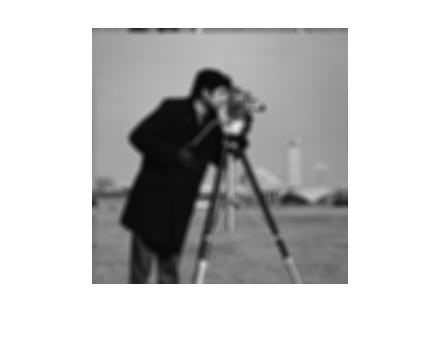

h = fspecial('disk',4);
% Read image and convert to double for FFT
cam = im2double(imread('cameraman.tif'));
hf = fft2(h,size(cam,1),size(cam,2));
cam_blur = real(ifft2(hf.*fft2(cam)));
imshow(cam_blur)

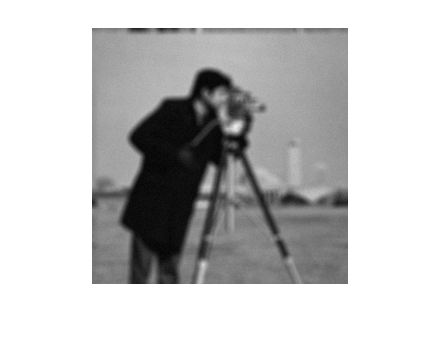

sigma_u = 10^(-40/20)*abs(1-0);
cam_blur_noise = cam_blur + sigma_u*randn(size(cam_blur));
imshow(cam_blur_noise)

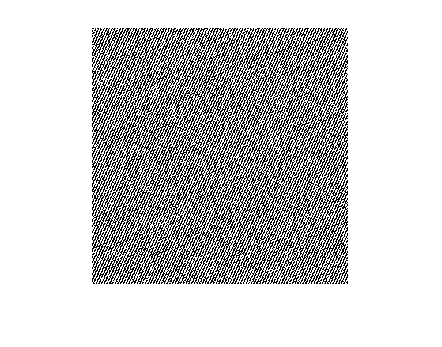

cam_inv = real(ifft2(fft2(cam_blur_noise)./hf));
imshow(cam_inv)

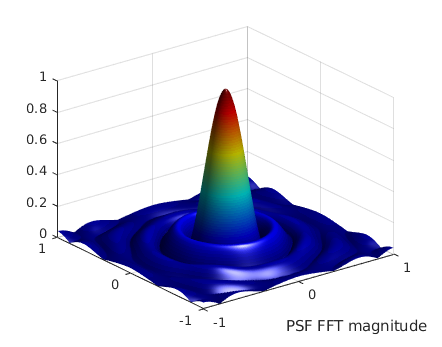

hf_abs = abs(hf);
surf([-127:128]/128,[-127:128]/128,fftshift(hf_abs))
shading interp, camlight, colormap jet
xlabel('PSF FFT magnitude')

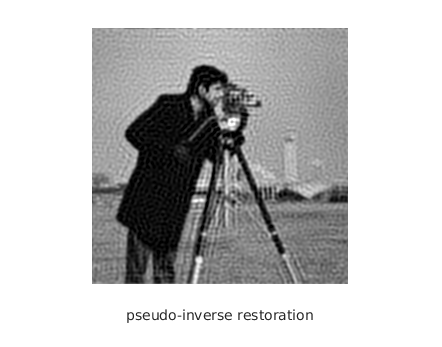

cam_pinv = real(ifft2((abs(hf) > 0.1).*fft2(cam_blur_noise)./hf));
imshow(cam_pinv)
xlabel('pseudo-inverse restoration')

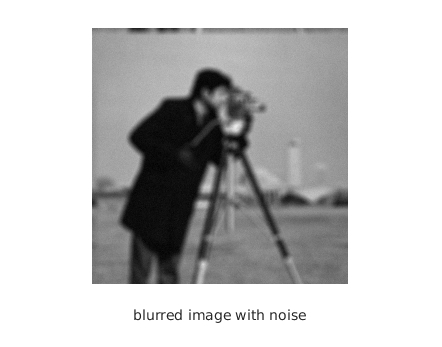

imshow(cam_blur_noise)
xlabel('blurred image with noise')

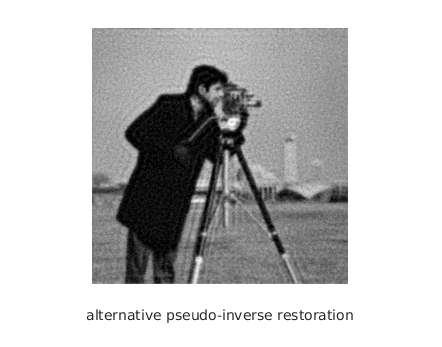

cam_pinv2 = real(ifft2(fft2(cam_blur_noise).*conj(hf)./(abs(hf).^2 + 1e-2)));
imshow(cam_pinv2)
xlabel('alternative pseudo-inverse restoration')

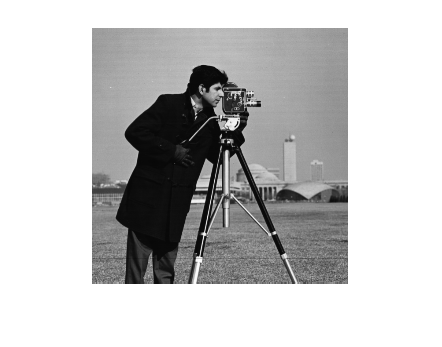

imshow(cam)